clear all
data=readtable("C:\Users\thoma\Downloads\book1.xlsx")

data = 8294×3 table
       Date       PX_LAST    TOT_RETURN_INDEX_GROSS_DVDS
    __________    _______    ___________________________

           NaT    3320.3               6843.8           
    28/02/2019    3298.3               6798.3           
    27/02/2019    3282.8               6766.4           
    26/02/2019    3289.3               6779.9           
    25/02/2019      3280               6760.7           
    22/02/2019    3270.6               6741.2           
    21/02/2019    3263.7               6727.1           
    20/02/2019    3259.5               6718.4           
    19/02/2019    3239.4                 6677           
    18/02/2019    3244.8               6688.1           
    15/02/2019    3241.3               6680.8           
    14/02/2019    3182.7                 6560           
    13/02/2019    3202.4                 6599           
    12/02/2019    3190

data=flipud(data)

data = 8294×3 table
       Date       PX_LAST    TOT_RETURN_INDEX_GROSS_DVDS
    __________    _______    ___________________________

    31/12/1986    900.82               900.82           
    01/01/1987    900.82               900.82           
    02/01/1987    891.78               891.78           
    05/01/1987    898.33               898.33           
    06/01/1987    902.32               902.32           
    07/01/1987    899.15               899.15           
    08/01/1987    887.37               887.37           
    09/01/1987    868.31               868.31           
    12/01/1987    879.41               879.41           
    13/01/1987    872.74               872.74           
    14/01/1987    876.39               876.39           
    15/01/1987    884.37               884.37           
    16/01/1987    883.78               883.78           
    19/01/1987    876.

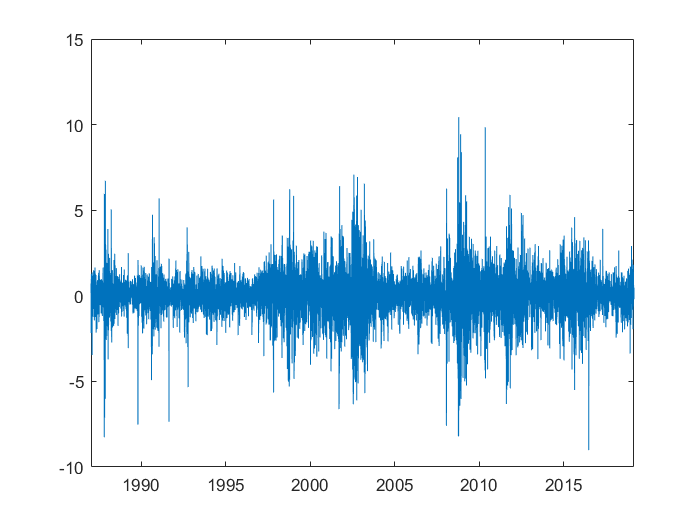


dates=datetime(data.Date(2:end),'Convertfrom','excel');

logreturn=100*diff(log(data.PX_LAST(2:end)));
plot(dates(3:end),logreturn(2:end))


logreturn

logreturn =    -1.0086
    0.7318
    0.4432
   -0.3519
   -1.3188
   -2.1713
    1.2702
   -0.7614
    0.4174
    0.9064


initialvalues = [1, 1,.05,0.7,0.03,.9]

initialvalues =     1.0000    1.0000    0.0500    0.7000    0.0300    0.9000


Ovenfor=[inf inf 1 inf inf inf]

Ovenfor =    Inf   Inf     1   Inf   Inf   Inf


Nedenfor=[0 0 -1 0 0 0]

Nedenfor =      0     0    -1     0     0     0


T=size(logreturn,1)

T = 8292

w = .06*.94.^(0:T-2); 
backCast= w*logreturn(2:end).^2;
options = optimset('fmincon'); 
options.Display = 'iter'; 
options.Algorithm = 'sqp'; 
estimates = fmincon(@APGARCH,initialvalues,[],[],[],[],Nedenfor,Ovenfor,@nlc,options,logreturn(2:1500),backCast);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           7    3.879686e+03     9.104e-01     1.000e+00     0.000e+00     1.490e+04  
Objective function returned NaN; trying a new point...
    1          15    1.984607e+03     0.000e+00     7.000e-01     1.346e+02     2.649e+05  
    2          23    1.242830e+03     0.000e+00     7.000e-01     8.377e+01     7.998e+04  
Objective function returned NaN; trying a new point...
    3          31    8.166073e+02     0.000e+00     7.000e-01     2.561e+01     2.517e+04  
Objective function returned NaN; trying a new point...
    4          39    6.470790e+02     0.000e+00     7.000e-01     7.807e+00     9.340e+03  
Objective function returned NaN; trying a new point...
    5          50    6.398337e+02     0.000e+00     2.401e-01     4.419e+00     7.085e+03  
Objective function returned NaN; trying a new 

initialvalues2=estimates

initialvalues2 =     0.9682    0.1324    0.4433    0.0515    0.0267    0.8404


[estimates,fval, exitflag,output,lambda,gradient,hessian] = fmincon(@APGARCH,initialvalues2,[],[],[],[],Nedenfor,Ovenfor,@nlc,options,logreturn(2:end),backCast);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           7    4.684028e+03     0.000e+00     1.000e+00     0.000e+00     8.188e+03  
Objective function returned Inf; trying a new point...
    1          51    4.665959e+03     0.000e+00     1.856e-06     1.256e-02     3.137e+03  
    2          71    4.658235e+03     0.000e+00     9.689e-03     4.942e-01     2.721e+03  
Objective function returned Inf; trying a new point...
    3          83    4.650199e+03     0.000e+00     1.681e-01     2.641e-01     1.682e+03  
Objective function returned Inf; trying a new point...
    4          92    4.643598e+03     0.000e+00     4.900e-01     6.487e-01     2.156e+04  
    5         104    4.622713e+03     0.000e+00     1.681e-01     2.090e-01     6.513e+03  
    6         116    4.604233e+03     0.000e+00     1.681e-01     3.039e-01     7.391e+03  
Objective

[ll,lls,h]=APGARCH(estimates,logreturn(2:end),backCast);
% % % res=resid(data,)
% % % res=resid(logreturn(:,1),h(:,1))
% % 
 ll

ll = 4.5847e+03

 lls

lls =     0.2738
    0.0798
    0.0189
    0.9838
    2.2065
    0.7338
    0.4199
    0.2817
    0.4570
    0.1306


 fval

fval = 4.5847e+03

 h

h =     1.0636
    0.9732
    0.8802
    0.8687
    1.1174
    1.6601
    1.5284
    1.5881
    1.4138
    1.2901


 exitflag

exitflag = 2

 output

output = struct with fields:
         iterations: 28
          funcCount: 325
          algorithm: 'sqp'
            message: 'Local minimum possible. Constraints satisfied.↵↵fmincon stopped because the size of the current step is less than↵the default value of the step size tolerance and constraints are ↵satisfied to within the selected value of the constraint tolerance.↵↵Stopping criteria details:↵↵Optimization stopped because the relative changes in all elements of x are↵less than options.StepTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.↵↵Optimization Metric                                           Options↵max(abs(delta_x./x)) =   9.99e-07                       StepTolerance =   1e-06 (default)↵relative max(constraint violation) =   0.00e+00   ConstraintTolerance =   1e-06 (selected)'
    constrviolation: 0
           stepsize: 1.0386e-06
       lssteplength: 0.0138
      firstorderopt

 lambda

lambda = struct with fields:
         eqlin: [0×1 double]
      eqnonlin: [0×1 double]
       ineqlin: [0×1 double]
    ineqnonlin: 0
         lower: [6×1 double]
         upper: [6×1 double]


 gradient

gradient =    -0.0018
   -0.0037
   -0.0004
   -0.0043
   -0.0032
   -0.0047


 hessian

hessian = 	1.0e+06 *

    0.0011    0.0364    0.0002    0.0438    0.0022    0.0494
    0.0364    1.3068    0.0019    1.5997    0.0903    1.7329
    0.0002    0.0019    0.0014   -0.0144   -0.0003   -0.0034
    0.0438    1.5997   -0.0144    2.6621    0.1267    2.3629
    0.0022    0.0903   -0.0003    0.1267    0.0182    0.1263
    0.0494    1.7329   -0.0034    2.3629    0.1263    2.4357


 eig(hessian)

ans = 	1.0e+06 *

    0.0000
    0.0010
    0.0116
    0.0276
    0.3008
    6.0843


 delta=estimates(:,1)

delta = 1.0283

alpha=estimates(:,2)

alpha = 0.0800

gamma=estimates(:,3)

gamma = 0.6741

omega=estimates(:,4)

omega = 0.0213

% konstant=0
konstant=estimates(:,5)

konstantderskabermartiginal = 0.0236

beta=estimates(:,6)

beta = 0.9176

mean((logreturn(2:end)-konstant)./sqrt(h))

ans = -0.0065


mean(((logreturn(2:end)-konstant)./sqrt(h)).^2)

ans = 1.0589


mean(((logreturn(2:end)-konstant)./sqrt(h)).^3)

ans = -0.6922


mean(((logreturn(2:end)-konstant)./sqrt(h)).^4)

ans = 9.5662


% logreturn(2:end)./sqrt(h)
% % mean(logreturn(2:end)./sqrt(h))
% % mean((logreturn(2:end)./sqrt(h)).^2)
% % mean((logreturn(2:end)./sqrt(h)).^3)
% % mean((logreturn(2:end)./sqrt(h)).^4)
% % 
% % % varians 
% % forskel=0.00001*estimates
% % bidrag=zeros(T-1,5);
% % for i=1:6
% %     
% %     j=forskel(i);
% %     delta=zeros(1,6);
% %     delta(i)=j;
% %     [~, loglikelidtover]= APGARCH(estimates+delta,logreturn(2:end),backCast);
% %     [~, loglikelidtunder]=APGARCH(estimates-delta,logreturn(2:end),backCast);
% %     bidrag(:,i)=(loglikelidtover-loglikelidtunder)/(2*j);
% % end
% % mean(bidrag)
% % I=bidrag'*bidrag/T
% % % Så skal J findes
% % J=hessian_beggesider(@APGARCH, estimates, logreturn(2:end), backCast)
% % J=J/T
% % Jinv=J\eye(length(J))
% % hessian\eye((length(hessian)))
% % 
% % % sum(h-mean(h))
% % % mean(sqrt(h)*fejlled)

% % % mean((logreturn(2:end)-konstant)./sqrt(h))
% % % 
% % % mean(((logreturn(2:end)-konstant)./sqrt(h)).^2)
% % % 
% % % mean(((logreturn(2:end)-konstant)./sqrt(h)).^3)
% % % 
% % % mean(((logreturn(2:end)-konstant)./sqrt(h)).^4)
% % 
% % % % mdl=arima(ar,,5)
% % % % estimatemdl=estimate()
% % % % 
% % % mean((h-mean(h)).^2)
% % % 
% % % mean()
% % % mean((h-mean(h)).^3)
% % % 
% % % mean((h-mean(h)).^4)
% % % 
% % % mean((h-mean(h)).^2)
% % % Så kombineres J og I for at få variansen 
% % var=Jinv*I*Jinv/T
% % se=sqrt(diag(var))
% % estimates
% % 
% % % simulation og test af modellen
% % 
% % name={'delta';'alpha';'gamma';'omega';'e';'beta'};
konstant=estimates(:,5)

konstantderskabermartiginal = 0.0236

z=(logreturn(2:end)-konstant)./sqrt(h)

z =     0.6867
    0.4253
   -0.4003
   -1.4402
   -2.0764
    0.9676
   -0.6349
    0.3125
    0.7425
   -0.0795


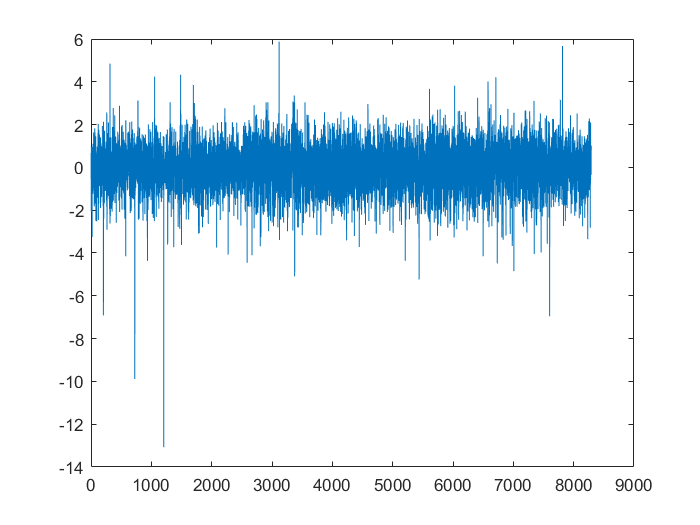

plot(z)

delta=estimates(:,1)

delta = 1.0283

alpha=estimates(:,2)

alpha = 0.0800

gamma=estimates(:,3)

gamma = 0.6741

omega=estimates(:,4)/10000

omega = 2.1261e-06

% konstant=0
konstant=estimates(:,5)/100

konstantderskabermartiginal = 2.3584e-04

beta=estimates(:,6)

beta = 0.9176



% [ts,pv]=ljungbox(z,12)

% [ts,pv]=lmtest(z,12,8294);
% zminus=-z.*1.96
% zplus=z.*1.96
% plot(zminus,zplus)
% standardafvigelse=(se')
% % parametre=[delta alpha gamma omega konstant beta]
mean((logreturn(2:end)-konstant)./sqrt(h))

ans = 0.0179


mean(((logreturn(2:end)-konstant)./sqrt(h)).^2)

ans = 1.0594


mean(((logreturn(2:end)-konstant)./sqrt(h)).^3)

ans = -0.6136


mean(((logreturn(2:end)-konstant)./sqrt(h)).^4)

ans = 9.4829

% % % delta=[estimates(:,1)-1.96*standardafvigelse(:,1), estimates(:,1), estimates(:,1)+1.96*standardafvigelse(:,1)]
% % % alpha=[estimates(:,2)-1.96*standardafvigelse(:,2), estimates(:,2), estimates(:,2)+1.96*standardafvigelse(:,2)]
% % % gamma=[estimates(:,3)-1.96*standardafvigelse(:,3), estimates(:,3), estimates(:,3)+1.96*standardafvigelse(:,3)]
% % % omega=[estimates(:,4)-1.96*standardafvigelse(:,4), estimates(:,4), estimates(:,4)+1.96*standardafvigelse(:,4)]
% % % beta=[estimates(:,6)-1.96*standardafvigelse(:,6), estimates(:,6), estimates(:,6)+1.96*standardafvigelse(:,6)]
% % 
% % tstatistic=parametre./standardafvigelse
% % table(name, parametre',standardafvigelse',tstatistic')

s=rng;
tilfaeldige=trnd(8294,121,1000000);
sigma2=zeros(121,100000);
sigma2(1,:)=0.00003878

sigma2 = 	1.0e+-4 *

    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

y=zeros(121,100000);
S=zeros(121,100000);
r=zeros(121,100000);
theta=zeros(121,100000);
% m=zeros(121,20000);
r(1,:)=0;
S(1,:)=1

S =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

theta(1,:)=0

theta =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

K=1

K = 1

y(1)=0

y =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

% optionspris=zeros(120,1000000);
m=zeros(121,100000)

m =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

m(1,:)=1

m =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

for j=1:100000
for i=2:120
    sigma2(i,j)=((omega + alpha*(abs(y(i-1,j))- gamma*y(i-1,j))^delta)+beta*sigma2(i-1,j)^(delta/2))^(2/delta);
    y(i,j)=sqrt(sigma2(i,j))*tilfaeldige(i,j)+konstant;
    r(i,j)=y(i,j)+r(i-1,j);
    S(i,j)=exp(r(i,j));
    theta(i,j)=(0.003/251)/sigma2(i,j)-1/2;
    m(i,j)=exp(y(i,j)*theta(i,j))/exp((1+theta(i,j))^2*sigma2(i,j)/2);

    
end
end
sigma2

sigma2 =     0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878
    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284

mean(prod(m(30)))

ans = 0.9959

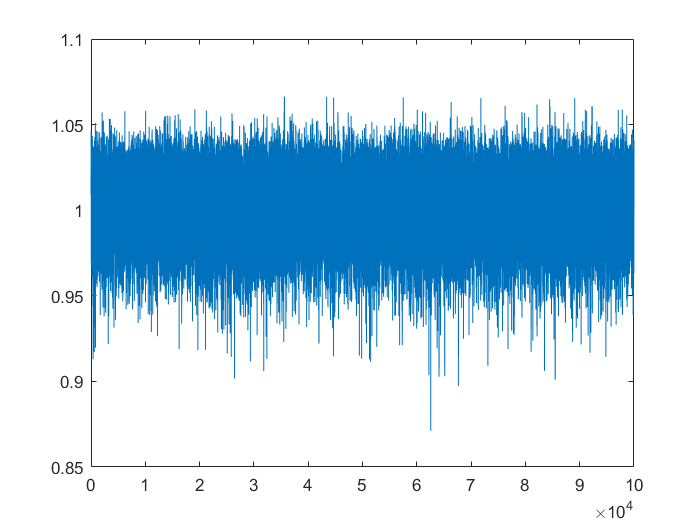

plot(mean(S(2:30,:)))

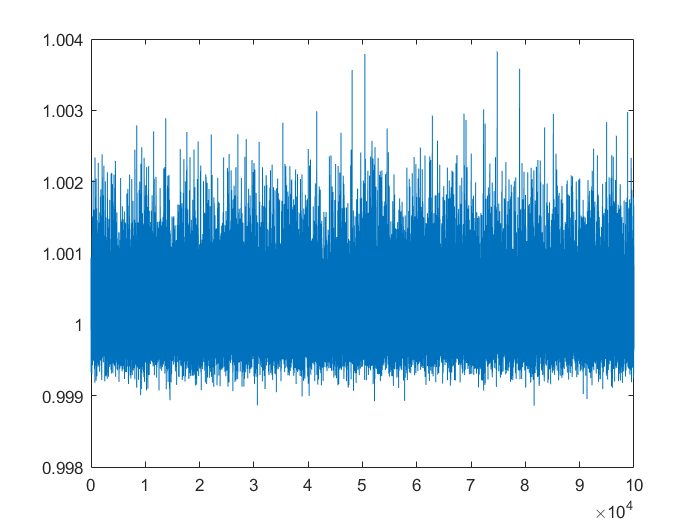

plot(mean(m(2:30,:)))

option=exp(-0.00001*30)*mean(max(S(30,:)-K,0))

option = 0.0138

option2=mean(max(S(30,:)-K,0))*mean(prod(m(30)))

option2 = 0.0138

option2=mean(max(S(30,:)-K,0)*prod(m(1:30)))*data.PX_LAST(end)

option2 = 47.2037

sigma2

sigma2 =     0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878    0.3878
    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284    0.3284

S

S =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    1.0016    0.9999    1.0009    0.9961    1.0031    1.0059    1.0049    1.0062    1.0007    0.9973    0.9984    1.0038    1.0043    0.9962    0.9913    1.0062    0.9958    0.9935    1.0070    0.9955    1.0113    0.9973    0.9947    1.0000    1.0034    1.0001    1.0044    1.0009    1.0017    1.0118    0.9907    1.0020    1.0046    0.9942    0.9993    0.9970    1.0063    0.9953    0.9945    1.0028    1.0024    1.0001    1.0038    1.0011    1.0036    0.9999    1.0011    1.0052    1.0031    0

m

m =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
    0.9998    1.0000    0.9999    1.0005    0.9996    0.9992    0.9993    0.9992    0.9999    1.0004    1.0002    0.9995    0.9994    1.0005    1.0012    0.9991    1.0006    1.0009    0.9990    1.0006    0.9985    1.0004    1.0007    1.0000    0.9995    1.0000    0.9994    0.9999    0.9998    0.9984    1.0013    0.9997    0.9994    1.0008    1.0001    1.0004    0.9991    1.0006    1.0007    0.9996    0.9997    1.0000    0.9995    0.9998    0.9995    1.0000    0.9998    0.9993    0.9996    1

mean(prod(m(1:30)))

ans = 1.0266

option2=mean(max(S(30,:)-K,0))*mean(prod(m(1:30)))*data.PX_LAST(end)

option2 = 47.2037



option=exp(-0.00001*60)*mean(max(S(60,:)-K,0))

option = 0.0204

option2=mean(max(S(60,:)-K,0))*mean(prod(m(1:60)))

option2 = 0.0224

option2=mean(max(S(60,:)-K,0))*mean(prod(m(1:60)))*data.PX_LAST(end)

option2 = 74.4563




option=exp(-0.00001*90)*mean(max(S(90,:)-K,0))

option = 0.0264

option2=mean(max(S(90,:)-K,0))*mean(prod(m(90)))

option2 = 0.0291

option2=mean(max(S(90,:)-K,0))*mean(prod(m(1:90)))*data.PX_LAST(end)

option2 = 158.6427


option=exp(-0.00001*120)*mean(max(S(120,:)-K,0))

option = 0.0325

option2=mean(max(S(120,:)-K,0)*prod(m(120)))*data.PX_LAST(end)

option2 = 133.3715


option2=mean(max(S(120,:)-K,0))*mean(prod(m(120)))

option2 = 0.0402

option2=mean(max(S(120,:)-K,0))*mean(prod(m(120)))*3000

option2 = 120.5052


option2=mean(max(S(120,:)-K,0))*mean(prod(m(120,:)))

option2 = Inf


% % 
% % optionspris30=mean(prod(M(30)))*mean(max(S(30,:)-K,0))
% % M
% % prod(M(30,:))
% % prod(M(30))
% % 
% % 
% % theta
% % S(30)
% % S(30,:)
% % M(i,j)
% % optionspris302=mean(M(30,:))*mean(max(S(30,:)-K,0))*3000
% % optionspris302=mean(M(30,:))*mean(max(S(30,:)-K,0))*3000
% % 
% % optionspris302=mean(M(60,:))*mean(max(S(60,:)-K,0))*3000
% % 
% % optionspris302=mean(M(90,:))*mean(max(S(90,:)-K,0))*3000
% % 
% % optionspris302=mean(M(120,:))*mean(max(S(120,:)-K,0))*3000
% % 
% % optionspris302=exp(-rent*30)*mean(max(S(30,:)-K,0))*3000
% % 
% % optionspris302=exp(-rent*60)*mean(max(S(60,:)-K,0))*3000
% % 
% % optionspris302=exp(-rent*90)*mean(max(S(90,:)-K,0))*3000
% % 
% % optionspris302=exp(-rent*120)*mean(max(S(120,:)-K,0))*3000
% % 
% % plot(mean(sqrt(sigma2)*252))
% % K=1
% % % A=[1 2 3 4; 5 6 7 8; 2 4 5 6]
% % % prod(A)
% % % prod(A,1)
% % % mean(prod(A,1))
% % % prod(A(1),1)
% % % prod(A,2)
% % % any(m==0)
% % % prod(m)
% % optionspris302=mean(prod(m(30,:),1))*mean(max(S(30)-K,0))
% % optionspris302=mean(prod(m(30),1))*mean(max(S(30)-K,0))
% % 
% % optionspris302=mean(prod(m(30,:),1))*mean(max(S(30)-K,0))*3000
% % optionspris302=mean(prod(m(30)))*mean(max(S(30)-K,0))*3000
% % 
% % optionspris12=mean(prod(m(120,:),1))*mean(max(S(120)-K,0))
% % optionspris12=mean(prod(m(120)))*mean(max(S(120)-K,0))
% % 
% % optionspris302=mean(prod(m(120,:),1))*mean(max(S(120)-K,0))*3000
% % optionspris302=mean(prod(m(120)))*mean(max(S(120)-K,0))*3000
% % 
% % optionspris302=mean(prod(m(60,:),1))*mean(max(S(60)-K,0))
% % optionspris302=mean(prod(m(60)))*mean(max(S(60)-K,0))
% % 
% % optionspris302=mean(prod(m(60,:),1))*mean(max(S(60)-K,0))*3000
% % optionspris302=mean(prod(m(60)))*mean(max(S(60)-K,0))*3000
% % 
% % optionspris302=mean(prod(m(90,:),1))*mean(max(S(90)-K,0))
% % optionspris302=mean(prod(m(90)))*mean(max(S(90)-K,0))
% % 
% % optionspris302=mean(prod(m(90,:),1))*mean(max(S(90)-K,0))*3000
% % optionspris302=mean(prod(m(90)))*mean(max(S(90)-K,0))*3000
% % 
% % optionspris302=mean(prod(m(30,:)))*mean(max(S(30)-K,0))
% % 
% % optionspris60=mean(prod(m(60),1))*mean(max(S(60)-K,0))
% % optionspris90=mean(prod(m(90),1))*mean(max(S(90)-K,0))
% % optionspris120=mean(prod(m(120,:),1))*mean(max(S(120)-K,0))
% % % mean(optionspris(30,:))
% % % mean(optionspris(60,:))
% % % mean(optionspris(90,:))
% % % mean(optionspris(120,:))
% % 
% % % 
% % % delta=[estimates(:,1)-1.96*se(:,1), estimates(:,1); estimates(:,1)+1.96*se(:,1)]
% % % alpha=[estimates(:,2)-1.96*se(:,2), estimates(:,2); estimates(:,2)+1.96*se(:,2)]
% % % gamma=[estimates(:,3)-1.96*se(:,3), estimates(:,3); estimates(:,3)+1.96*se(:,3)]
% % % omega=[estimates(:,4)-1.96*se(:,4), estimates(:,4); estimates(:,4)+1.96*se(:,4)]
% % % beta=[estimates(:,6)-1.96*se(:,6), estimates(:,6); estimates(:,6)+1.96*se(:,6)]
% % % m=zeros(120,1000000,3);
% % % M=zeros(120,1000000,3);
% % % optionspris=zeros(120,1000000,3);
% % % M(1,:,:)=1;
% % % r=zeros(120,1000000,3); 
% % % K=1;
% % %  sigma2=zeros(120,1000000,3);
% % %  y=zeros(120,1000000,3);
% % %  S=zeros(120,1000000,3);
% % %  theta=zeros(120,1000000,3);
% % % 
% % % r=zeros(120,1000000,3);
% % % 
% % % 
% % % for n=1:3
% % % for j=1:1000000
% % % for i=2:120
% % %     sigma2(i,j,n)=((omega(n) + alpha(n)*((abs(tilfaeldige(i-1,j))- gamma(n)*tilfaeldige(i-1,j)))^delta(n))+beta(n)*sigma2(i-1,j)^(delta(n)/2)).^(2/delta(n));
% % %     y(i,j,n)=sqrt(sigma2(i,j,n))*tilfaeldige(i,j)+konstant(i,j,n);
% % %     r(i,j,n)=y(i,j,n)+r(i-1,j,n);
% % %     S(i,j,n)=exp(r(i,j,n)/100);
% % %     theta(i,j,n)=0.02./sigma2(i,j,n)-1/2;
% % %     m(i,j,n)=(exp(y(i,j,n)./100.*theta(i,j,n)))./exp((1+theta(i,j,n).*sigma2(i,j,n))./2);
% % %     M(i,j,n)=prod(m(i,j,n),1);
% % %     optionspris(i,j,n)=M(i,j)*max(S(i,j,n)-K,0);      
% % % end
% % % end
% % % end
% % % 
% % % S=900
% % % % any(S(30)<S(1)*1.2)
% % %  K=[0.6,0.8,1,1.2,1.4];
% % % m(30)
% % % 
% % % mean(optionspris);
% % % 
% % % 
% % % for i=1:5
% % % optionspris302(i)=mean(m(30,:,2))*mean(max(S(30,:,2)-K(i),0));
% % % optionspris60(i)=mean(m(60,:,2))*mean(max(S(60,:,2)-K(i),0));
% % % optionspris90(i)=mean(m(90,:,2))*mean(max(S(90,:,2)-K(i),0));
% % % optionspris120(i)=mean(m(120,:,2))*mean(max(S(120,:,2)-K(i),0));
% % % end
% % % 
% % % optionspris302
% % % optionspris60
% % % optionspris90
% % % optionspris120
% % % 
% % % M=m
% % % optionspris
% % % mean(M)
% % % mean(optionspris(30,:,2))*3500
% % % mean(optionspris(60,:,2))*3500
% % % mean(optionspris(90,:,2))*3500
% % % mean(optionspris(120,:,2))*3500
% % % % optionspris30=mean(m(30,:))*sum(max(S(30,:)-K,0))./1000000
% % % % 
% % % % for i=1:30
% % % % optionspris30=mean(max(S(i+30,:)-K,0));
% % % % end
% % % % for i=1:60
% % % % optionspris60=mean(max(S(i+60,:)-K,0));
% % % % end
% % % % for i=1:90
% % % % optionspris90=mean(max(S(i+90,:)-K,0));
% % % % end
% % % % for i=1:120
% % % % optionspris120=mean(max(S(i+120,:)-K,0));
% % % % end
% % % optionspris30
% % % optionspris60
% % % optionspris90
% % % optionspris120
% % % 
% % % data=readtable("C:\Users\thoma\Downloads\book1.xlsx")
% % %  data=flipud(data)
% % % 
% % %   
% % % first=data.PX_LAST(1)
% % % reloptionspris30=optionspris30*first
% % % reloptionspris60=optionspris60*first
% % % reloptionspris90=optionspris90*first
% % % reloptionspris120=optionspris120*first
% % % 
% % % 
% % % mom1=mean(logreturn(2:end)./sqrt(h))
% % % mom2=mean((logreturn(2:end)./sqrt(h)).^2)
% % % mom3=mean((logreturn(2:end)./sqrt(h)).^3)
% % % mom4=mean((logreturn(2:end)./sqrt(h)).^4)
% % % % 
% % % % 
% % % % syms op
% % % % T=30;
% % % % S0=S(1);
% % % % d1=(log(S0/K)+(r+op/2)*T)/(sqrt(T*op))
% % % % d2=d1-sqrt(op*T)
% % % % c = optionspris30==S0*cdf('T',d1,4)-K*exp(-r*T)*cdf('T',d2,4)
% % % 
% % % % c = optionspris30==S0*cdf('T',d1,mom1,mom2,mom3,mom4)-K*exp(-r*T)*cdf('T',d2,mom1,mom2,mom3,mom4)
% % % implieds=solve(c,op)
% % % % r=1.03^(1/250)-1;
% % % % r=0;
% % % % % x=zeros(1,1)
% % % syms op
% % % T=60;
% % % S0=S(1);
% % % d1=(log(S0/K)+(r+op/2)*T)/(sqrt(T*op));
% % % d2=d1-sqrt(op*T);
% % % c = optionspris60==S0*cdf('T',d1,8285)-K*exp(-r*T)*cdf('T',d2,8285)
% % % implieds=solve(c,op)
% % % 
% % % syms op
% % % T=90;
% % % S0=S(1);
% % % d1=(log(S0/K)+(r+op/2)*T)/(sqrt(T*op));
% % % d2=d1-sqrt(op*T);
% % % c = optionspris90==S0*cdf('T',d1,8285)-K*exp(-r*T)*cdf('T',d2,8285)
% % % implieds=solve(c,op)
% % % % 
% % % % h
% % % syms op
% % % T=120;
% % % S0=S(1);
% % % d1=(log(S0/K)+(r+op/2)*T)/(sqrt(T*op));
% % % d2=d1-sqrt(op*T);
% % % c = optionspris120==S0*cdf('T',d1,8285)-K*exp(-r*T)*cdf('T',d2,8285)
% % % implieds=solve(c,op)
% % % 
% % % syms op
% % % T=30;
% % % S0=S(1);
% % % d1=(log(S0/K)+(r+op/2)*T)/(sqrt(T*op));
% % % d2=d1-sqrt(op*T);
% % % c = optionspris30==S0*cdf('Normal',d1,0,1,0,3)-K*exp(-r*T)*cdf('Normal',d2,0,1,0,3)